# Monster Mission Control

#### Run Experiment:

% Set Up Labjack
grab_jack

Opened a LabJack with Device type: 7, Connection type: 1,
Serial number: 470031918, IP address: 0.0.0.0, Port: 0,
Max bytes per MB: 64


set_input_mode

Input mode set for DIO0-DIO22


get_DAC_addresses

% Configure
animal_code = "Monster6_11";
percent_deprived = 82.38;
experiment_name = "Monster6";
session_name = "X_FiberAcclimation";
n_trials = 10;
enter_time_limit = 60 * 1000; % enter s, give ms
reward_volume = 50;% ms
loom = 0;
crescendo = 0;
sample_rate = 2000;

m = findall(0,'type','figure');
delete(m);

% Open an arduino port and send those variables
arduino_obj = serialport("COM6",9600);
configureTerminator(arduino_obj,"CR");
pause(2);

writeline(arduino_obj, string(n_trials));
writeline(arduino_obj, string(enter_time_limit));
writeline(arduino_obj, string(reward_volume));
writeline(arduino_obj, string(loom));
writeline(arduino_obj, string(crescendo));

% get directory name to save files to
home = pwd;
save_dir = fullfile(home, "Data", experiment_name, session_name, animal_code);
mkdir(save_dir);

% DAC0 Streamout 
DAC0_amplitude = 0.14; % V
DAC0_frequency = 167 ; % Hz
DAC0_baseline = 0.46; % V
DAC0_vals = generateDACcosinewave( ...
    DAC0_amplitude, ...
    DAC0_frequency, ...
    DAC0_baseline ...
    );
LabJack.LJM.eWriteName(handle, 'STREAM_OUT0_TARGET', DAC0_addy);
LabJack.LJM.eWriteName(handle, 'STREAM_OUT0_BUFFER_SIZE', 512);
LabJack.LJM.eWriteName(handle, 'STREAM_OUT0_ENABLE', 1);
LabJack.LJM.eWriteName(handle, 'STREAM_OUT0_LOOP_SIZE', length(DAC0_vals));
for i = 1:length(DAC0_vals)
    LabJack.LJM.eWriteName(handle, 'STREAM_OUT0_BUFFER_F32', DAC0_vals(i));
end  
LabJack.LJM.eWriteName(handle, 'STREAM_OUT0_SET_LOOP', 1);
fprintf("DAC0 set to stream at %d Hz with amplitude %.2f V and baseline %.2f V", DAC0_frequency, DAC0_amplitude, DAC0_baseline)

DAC0 set to stream at 167 Hz with amplitude 0.14 V and baseline 0.46 V


% DAC1 Streamout
DAC1_amplitude = 0.13; % V
DAC1_frequency = 223; % Hz
DAC1_baseline = 0.46; % V
DAC1_vals = generateDACcosinewave( ...
    DAC1_amplitude, ...
    DAC1_frequency, ...
    DAC1_baseline ...
    );
LabJack.LJM.eWriteName(handle, 'STREAM_OUT1_TARGET', DAC1_addy);
LabJack.LJM.eWriteName(handle, 'STREAM_OUT1_BUFFER_SIZE', 512);
LabJack.LJM.eWriteName(handle, 'STREAM_OUT1_ENABLE', 1);
LabJack.LJM.eWriteName(handle, 'STREAM_OUT1_LOOP_SIZE', length(DAC1_vals));
for i = 1:length(DAC1_vals)
    LabJack.LJM.eWriteName(handle, 'STREAM_OUT1_BUFFER_F32', DAC1_vals(i));
end
LabJack.LJM.eWriteName(handle, 'STREAM_OUT1_SET_LOOP', 1);
fprintf("DAC1 set to stream at %d Hz with amplitude %.2f V and baseline %.2f V", DAC1_frequency, DAC1_amplitude, DAC1_baseline)

DAC1 set to stream at 223 Hz with amplitude 0.13 V and baseline 0.46 V


% Save Configuration Information
cd(save_dir)
save( ...
    "configset.mat", ...
    "animal_code", ...
    "percent_deprived", ...
    "experiment_name", ...
    "session_name", ...
    "n_trials", ...
    "enter_time_limit", ...
    "reward_volume", ...
    "loom", ...
    "crescendo", ...
    ... % DAC Values
    "DAC0_amplitude", ...
    "DAC0_frequency", ...
    "DAC0_baseline", ...
    "DAC1_amplitude", ...
    "DAC1_frequency", ...
    "DAC1_baseline" ...
    )
disp("Photometry Configuration Saved to configset.mat")

Photometry Configuration Saved to configset.mat



% Read Configuration
numAddressesIn = 16;
aScanListNames = NET.createArray('System.String', numAddressesIn);

aScanListNames(1) = 'AIN0';         % photodetector green
aScanListNames(2) = 'AIN1';         % photodetector red
aScanListNames(3) = 'AIN2';         % DAC0 167Hz Mod Copy (green)
aScanListNames(4) = 'AIN3';         % DAC1 223Hz Mod Copy (red)
aScanListNames(5) = 'DIO0';         % Arduino D2: -------
aScanListNames(6) = 'DIO1';         % Arduino D3: -------
aScanListNames(7) = 'DIO2';         % Arduino D4: enterIR
aScanListNames(8) = 'DIO3';         % Arduino D5: trigIR
aScanListNames(9) = 'DIO4';         % Arduino D6: nestIR
aScanListNames(10) = 'DIO5';        % Arduino D7: -------
aScanListNames(11) = 'DIO6';        % Arduino D8: loom
aScanListNames(12) = 'DIO7';        % Arduino D9: crescendo
aScanListNames(13) = 'DIO8';        % Arduino D10: Trial
aScanListNames(14) = 'DIO9';        % Arduino D11: Running
aScanListNames(15) = 'DIO10';       % Arduino D12: Lick
aScanListNames(16) = 'DIO11';       % Arduino D13: Reward

% where in temp can you find the value of the running signal 
running_idx = 14;

%   Scan list addresses to stream
aScanList = NET.createArray('System.Int32', (numAddressesIn + 2));
aTypes = NET.createArray('System.Int32', numAddressesIn);
LabJack.LJM.NamesToAddresses(numAddressesIn, aScanListNames, aScanList, aTypes);

%   Add the scan list outputs to the end of the scan list
aScanList(numAddressesIn+1) = 4800;     % STREAM_OUT0
aScanList(numAddressesIn+2) = 4801;     % STREAM_OUT1
scanRate = double(sample_rate);                % Scans per second
scansPerRead = sample_rate;                    % Scans returned by eStreamRead call

aData = NET.createArray('System.Double', numAddressesIn*scansPerRead);

% dictate the range of values for analog inputs
numFrames = 11;

aNames = NET.createArray('System.String', numFrames);
aNames(1) = 'AIN_ALL_NEGATIVE_CH';
aNames(2) = 'AIN0_RANGE';
aNames(3) = 'AIN1_RANGE';
aNames(4) = 'AIN2_RANGE';
aNames(5) = 'AIN3_RANGE';
aNames(6) = 'AIN4_RANGE';
aNames(7) = 'AIN5_RANGE';
aNames(8) = 'AIN6_RANGE';
aNames(9) = 'AIN7_RANGE';
aNames(10) = 'STREAM_SETTLING_US';
aNames(11) = 'STREAM_RESOLUTION_INDEX';

aValues = NET.createArray('System.Double', numFrames);
aValues(1) = LJM_CONSTANTS.GND;
aValues(2) = 10.0;
aValues(3) = 10.0;
aValues(4) = 10.0;
aValues(5) = 10.0;
aValues(6) = 10.0;
aValues(7) = 10.0;
aValues(8) = 10.0;
aValues(9) = 10.0;
aValues(10) = 0;
aValues(11) = 0;

% Configure and start stream (eStreamStart)
numAddresses = aScanList.Length;
[~, scanRate] = LabJack.LJM.eStreamStart(handle, scansPerRead, numAddresses, aScanList, scanRate);
disp(['Stream ready with a scan rate of ' num2str(scanRate) ' Hz.'])

Stream ready with a scan rate of 2000 Hz.


maxRequests = 3600;
totalScans = 0;
curSkippedSamples = 0;
totalSkippedSamples = 0;
DATAM = zeros(maxRequests,scanRate*numAddressesIn);
cd(save_dir);
disp("Ready to Read")

Ready to Read



% Wait to start reading till start from arduino
while true
    [~, devScanBL, ljmScanBL] = LabJack.LJM.eStreamRead(handle, aData, 0, 0);
    totalScans = totalScans + scansPerRead;
    DATAM(i,:)=aData.double;
    temp = aData.double;
    trigstate = mean(temp(running_idx:numAddressesIn:end));
    if trigstate > 0.5
        break
    end
end
disp("Started Read")

Started Read


% Read until receiving stop from arduino
for i = 1:maxRequests
    [~, devScanBL, ljmScanBL] = LabJack.LJM.eStreamRead(handle, aData, 0, 0);
    totalScans = totalScans + scansPerRead;
    DATAM(i,:)=aData.double;
    temp = aData.double;
    save(sprintf('Raw_%d.mat',i+1000),'temp')
    curSkippedSamples = sum(double(aData) == -9999.0);
    totalSkippedSamples = totalSkippedSamples + curSkippedSamples;
    trigstate = mean(temp(running_idx:numAddressesIn:end));
    if trigstate < 0.5
        break
    end
end

disp("Complete")

Complete



LabJack.LJM.eStreamStop(handle); % stop stream
LabJack.LJM.Close(handle); % close handle

disp("LabJack Closed")

LabJack Closed


### Data Analysis

% For testing 
numAddressesIn = 16;
sample_rate = 2000;
load("configset.mat")
%

% Plot colors
custom_blue = [114 147 203]/255;
custom_orange = [225 151 76]/255;
custom_purple = [144, 103, 167]/255;
custom_green = [132 186 91]/255;
custom_grey = [211, 211, 211]/255;

delete("Raw_1001.mat"); 

D=dir('Raw_*.mat');
filename={D.name};
output=zeros(1,(length(filename)*(sample_rate*numAddressesIn)));

for i=1:length(D)
    load(filename{i});
    output(((i-1)*(sample_rate*numAddressesIn)+1):(i*(sample_rate*numAddressesIn)))=temp;
end
totalLen = length(output);

% Create variables which contain the relevant values
raw_PD_green    =output(find(mod(1:totalLen,numAddressesIn)==1));     % photodetector green
raw_PD_red      =output(find(mod(1:totalLen,numAddressesIn)==2));     % photodetector red
Mod_green       =output(find(mod(1:totalLen,numAddressesIn)==3));     % DAC0 167Hz Mod Copy (green)
Mod_red         =output(find(mod(1:totalLen,numAddressesIn)==4));     % DAC1 223Hz Mod Copy (red)
d2_null         =output(find(mod(1:totalLen,numAddressesIn)==5));     % d2: -
d3_null         =output(find(mod(1:totalLen,numAddressesIn)==6));     % d3: -
d4_enterIR      =output(find(mod(1:totalLen,numAddressesIn)==7));     % d4: enterIR
d5_trigIR       =output(find(mod(1:totalLen,numAddressesIn)==8));     % d5: trigIR
d6_nestIR       =output(find(mod(1:totalLen,numAddressesIn)==9));     % d6: nestIR
d7_null         =output(find(mod(1:totalLen,numAddressesIn)==10));    % d7: -
d8_loom         =output(find(mod(1:totalLen,numAddressesIn)==11));    % d8: loom
d9_crescendo    =output(find(mod(1:totalLen,numAddressesIn)==12));    % d9: crescendo
d10_trial       =output(find(mod(1:totalLen,numAddressesIn)==13));    % d10: trial
d11_running     =output(find(mod(1:totalLen,numAddressesIn)==14));    % d11: running
d12_lick        =output(find(mod(1:totalLen,numAddressesIn)==15));    % d12: Lick
d13_reward      =output(find(mod(1:totalLen,numAddressesIn)==16));    % d13: Reward

### Mod Signals

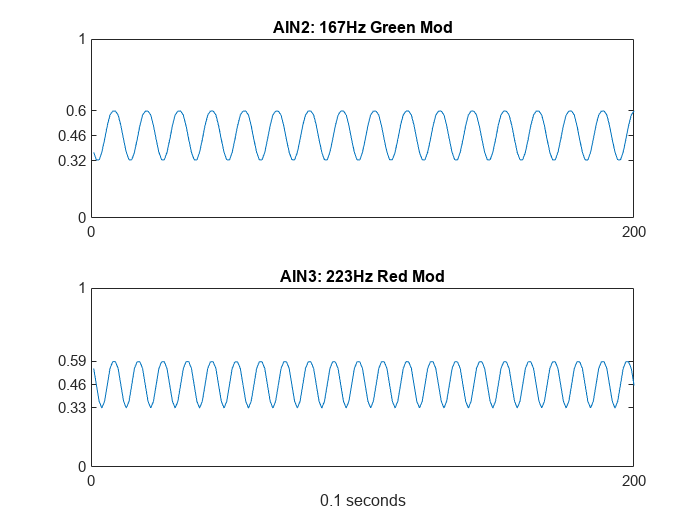

figure;
ax = [];
ax(1) = subplot(2,1,1);plot(Mod_green);title('AIN2: 167Hz Green Mod');xlim([0 200]);ylim([0 1]);xticks([0 200]);yticks([0 (DAC0_baseline-DAC0_amplitude) DAC0_baseline (DAC0_baseline+DAC0_amplitude) 1]);
ax(2) = subplot(2,1,2);plot(Mod_red);title('AIN3: 223Hz Red Mod');xlim([0 200]);ylim([0 1]);xticks([0 200]);xlabel("0.1 seconds");yticks([0 (DAC1_baseline-DAC1_amplitude) DAC1_baseline (DAC1_baseline+DAC1_amplitude) 1])
linkaxes(ax,'x');

### Raw PD signals

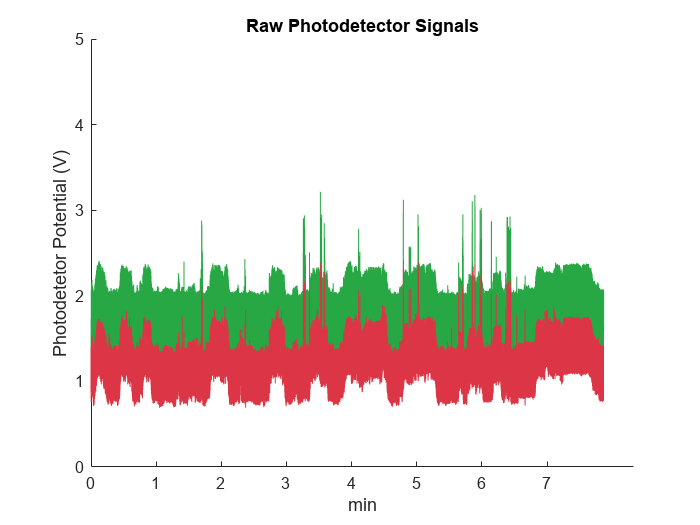

figure;
samples_per_minute = 60*sample_rate;
hold on
g = plot(raw_PD_green, 'color', "#28a745");
r = plot(raw_PD_red, 'color', "#dc3545");
title("Raw Photodetector Signals")
xticks(0:samples_per_minute:length(raw_PD_green));
xticklabels = 0:(length(raw_PD_green) / samples_per_minute);
set(gca, 'xticklabel', xticklabels);
ylabel("Photodetetor Potential (V)");
ylim([0 5]);
yticks(0:1:5)
xlabel("min");

#### Demodulate Photodetector Signals

Spectrum window 0.064 sec; 128 samples at 2000 Hz


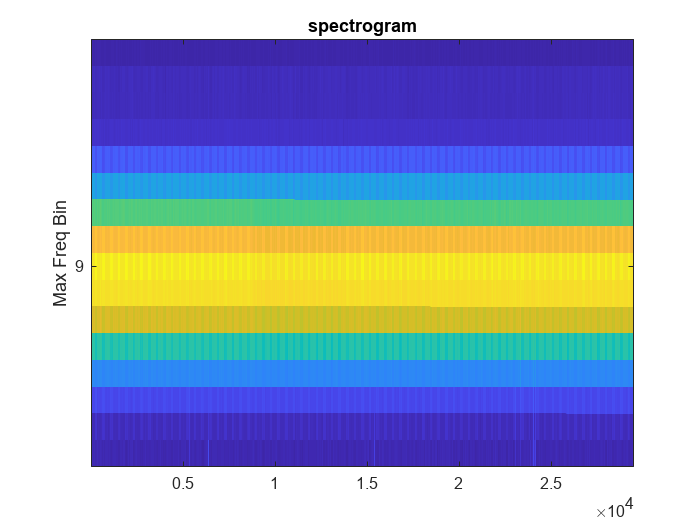

% Creates a params struct
params.freqStep   = 5;          % Step size in Hz for freqency calculations
params.freqRange1 = [125 200];  % Min and max frequency range for channel 1 (target 167 Hz) (ex 125-200)
params.freqRange2 = [200 275];  % Min and max frequency range for channel 2 (target 223 Hz) (ex 200-275)
params.winSize = 0.04;          % Target window size (in sec) for FFT frequency calc (80 samples)
params.spectSample = 0.01;      % Step size for spectrogram (sec)
params.inclFreqWin = 2;         % Number of frequency bins to average (on either side of peak freq)
params.filtCut = 100;           % Cut off frequency for low pass filter of processed data
params.filtCutOsc = 500;        % Cut-off frequency for low-pass filter of oscillation data.
params.dsRate = 0.05;           % Time steps for down-sampling (seconds) (average of every 100 samples)

% Calculate Spectrograms for Channel 1 and 2
useFreqRange1 = params.freqRange1(1):params.freqStep:params.freqRange1(2);
[filtTimes, filtSig1, rawSig1, spectFreqs1, spectAmpVals1] = sfoReadFibPhot(raw_PD_green, 2000, useFreqRange1, params);

Spectrum window 0.064 sec; 128 samples at 2000 Hz


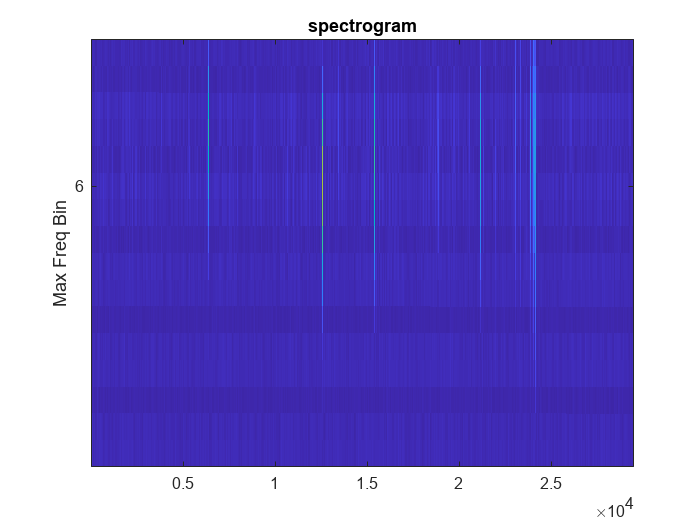

useFreqRange2 = params.freqRange2(1):params.freqStep:params.freqRange2(2);
[filtTimes, filtSig2, rawSig2, spectFreqs2, spectAmpVals2] = sfoReadFibPhot(raw_PD_red, 2000, useFreqRange2, params);

% Determine downsampled time points in output data set
dsTimes = filtTimes(1):params.dsRate:filtTimes(end); 

### Photobleaching Correction

% Fit: Fit each channel to exponential decay for photobleaching correction
pbFit1 = fit(filtTimes',filtSig1','exp2'); 
pbFit2 = fit(filtTimes',filtSig2','exp2');

% Correction: Divide filtered signal by exponential decay to correct for photobleaching
pbVals1 = (filtSig1' ./ double(pbFit1(filtTimes)))';
pbVals2 = (filtSig2' ./ double(pbFit2(filtTimes)))';

% Downsample raw (uncorrected) data
g_dsVals_raw = interp1(filtTimes,filtSig1',dsTimes,'spline');
r_dsVals_raw = interp1(filtTimes,filtSig2',dsTimes,'spline');

% Downsample photobleaching-corrected data
g_dsVals = interp1(filtTimes,pbVals1,dsTimes,'spline');
r_dsVals = interp1(filtTimes,pbVals2,dsTimes,'spline');

#### dF/F

Fs=20; % Downsampled Frequency = 20Hz
g_0 = running_percentile(g_dsVals, floor(Fs*10), 10);
g_dff = g_dsVals'./g_0 - 1;
g_dff = g_dff';
r_0 = running_percentile(r_dsVals, floor(Fs*10), 10);
r_dff = r_dsVals'./r_0 - 1;
r_dff = r_dff';

#### Make Derivative Raw Trace

g_deriv = diff(g_dsVals');
r_deriv = diff(r_dsVals');
g_deriv = g_deriv';
r_deriv = r_deriv';
g_deriv = [zeros(1, max(0, 1)), g_deriv];
r_deriv = [zeros(1, max(0, 1)), r_deriv];

#### Z-score raw trace and diff

zscore_g_dsVals = zscore(g_dsVals);
zscore_r_dsVals = zscore(r_dsVals);
zscore_g_deriv = zscore(g_deriv);
zscore_r_deriv = zscore(r_deriv);

#### Plot 

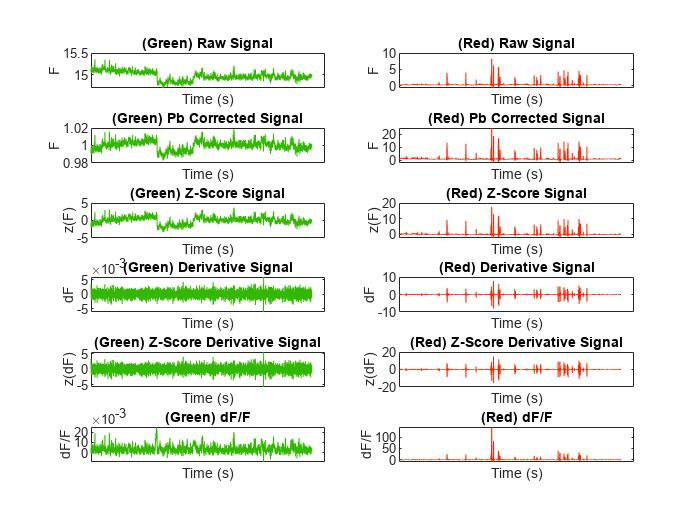

figure;
ax = [];

% Green________________________________________________________________________________________________________

% (Green) Raw Signal
ax(1) = subplot(6,2,1);
plot(dsTimes,g_dsVals_raw, "Color", "#32B800"); title('(Green) Raw Signal');
xlabel('Time (s)')
ylabel('F')
xticks([])

% (Green) Photobleaching Corrected Signal
ax(2) = subplot(6,2,3);
plot(dsTimes,g_dsVals, "Color", "#32B800"); title('(Green) Pb Corrected Signal');
xlabel('Time (s)')
ylabel('F')
xticks([])

% (Green) Z-Score Signal 
ax(3) = subplot(6,2,5);
plot(dsTimes,zscore_g_dsVals, "Color", "#32B800"); title('(Green) Z-Score Signal');
xlabel('Time (s)')
ylabel('z(F)')
xticks([])

% (Green) Derivative Signal
ax(4) = subplot(6,2,7);
plot(dsTimes,g_deriv, "Color", "#32B800"); title('(Green) Derivative Signal');
xlabel('Time (s)')
ylabel('dF')
xticks([])

% (Green) Z-Score Derivative Signal 
ax(5) = subplot(6,2,9);
plot(dsTimes,zscore_g_deriv, "Color", "#32B800"); title('(Green) Z-Score Derivative Signal');
xlabel('Time (s)')
ylabel('z(dF)')
xticks([])

% (Green) dF/F
ax(6) = subplot(6,2,11);
plot(dsTimes,g_dff, "Color", "#32B800"); title('(Green) dF/F');
xlabel('Time (s)')
ylabel('dF/F')
xticks([])

% Red________________________________________________________________________________________________________

% (Red) Raw Signal
ax(7) = subplot(6,2,2);
plot(dsTimes,r_dsVals_raw, "Color", "#FF2400"); title('(Red) Raw Signal');
xlabel('Time (s)')
ylabel('F')
xticks([])

% (Red) Photobleaching Corrected Signal
ax(8) = subplot(6,2,4);
plot(dsTimes,r_dsVals, "Color", "#FF2400"); title('(Red) Pb Corrected Signal');
xlabel('Time (s)')
ylabel('F')
xticks([])

% (Red) Z-Score Signal 
ax(9) = subplot(6,2,6);
plot(dsTimes,zscore_r_dsVals, "Color", "#FF2400"); title('(Red) Z-Score Signal');
xlabel('Time (s)')
ylabel('z(F)')
xticks([])

% (Red) Derivative Signal
ax(10) = subplot(6,2,8);
plot(dsTimes,r_deriv, "Color", "#FF2400"); title('(Red) Derivative Signal');
xlabel('Time (s)')
ylabel('dF')
xticks([])

% (Red) Z-Score Derivative Signal 
ax(11) = subplot(6,2,10);
plot(dsTimes,zscore_r_deriv, "Color", "#FF2400"); title('(Red) Z-Score Derivative Signal');
xlabel('Time (s)')
ylabel('z(dF)')
xticks([])

% (Red) dF/F
ax(12) = subplot(6,2,12);
plot(dsTimes,r_dff, "Color", "#FF2400"); title('(Red) dF/F');
xlabel('Time (s)')
ylabel('dF/F')
xticks([])

linkaxes(ax, 'x');

## Digital Data

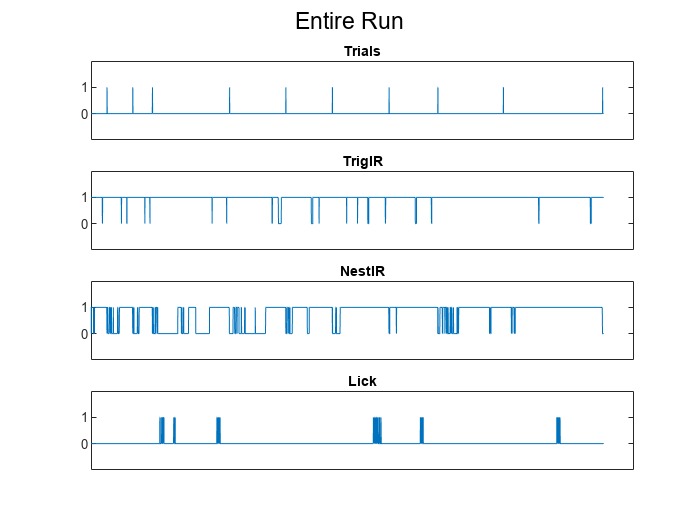

figure;
ax = [];
ax(1) = subplot(4,1,1);plot(d10_trial);title('Trials');yticks([0 1]);xticks([]);ylim([-1 2]);
ax(2) = subplot(4,1,2);plot(d5_trigIR);title('TrigIR');yticks([0 1]);xticks([]);ylim([-1 2]);
ax(3) = subplot(4,1,3);plot(d6_nestIR);title('NestIR');yticks([0 1]);xticks([]);ylim([-1 2]);
ax(4) = subplot(4,1,4);plot(d12_lick);title('Lick');yticks([0 1]);xticks([]);ylim([-1 2]);
sgtitle("Entire Run")
linkaxes(ax,'x');

## Trial Data

Data = table();

trial_indices = [1 find(diff(d10_trial) == 1)];
ds_trial_indices = [1 round(trial_indices(2:end)/100)];
n_trials = length(trial_indices) - 1;

% Data Vector Initialization
sucessses = zeros(n_trials, 1);
failure_to_lick = zeros(n_trials, 1);
failure_to_trigger = zeros(n_trials, 1);
trial_duration = zeros(n_trials, 1);
latency_to_trigger = zeros(n_trials, 1);
escape_after_trigger = zeros(n_trials, 1);
trigger_to_lick = zeros(n_trials, 1);
time_spent_licking = zeros(n_trials, 1);
escape_after_last_lick = zeros(n_trials, 1);
latency_to_lick = zeros(n_trials, 1);

first_trigger_on_idx = zeros(n_trials, 1);
last_trigger_off_idx = zeros(n_trials, 1);
first_lick_idx = zeros(n_trials, 1);
last_lick_idx = zeros(n_trials, 1);
first_nest_on_idx = zeros(n_trials, 1);
last_nest_on_idx = zeros(n_trials, 1);

% Determine max_trial_length for plotting purposes
max_trial_length = 0;
for i = 1:n_trials
    start_idx = trial_indices(i);
    end_idx = trial_indices(i+1);
    trial_length = end_idx - start_idx + 1;
    if trial_length > max_trial_length
        max_trial_length = trial_length;
    end
end

Visual = figure;
for i = 1:n_trials
    
    subplot_idx_odds = 1:2:((n_trials*2)-1); 
    subplot_idx_evens = 2:2:((n_trials*2));

    subplot(n_trials*2, 1, subplot_idx_odds(i));
    hold on
    start_idx = trial_indices(i);
    end_idx = trial_indices(i+1);
    trial_length = end_idx-start_idx;

    % Nest IR
    nest = d6_nestIR(start_idx:end_idx);
    nest_on = find(diff(nest) == -1); % for IR sensors, diff() = -1 means onset
    nest_off = find(diff(nest) == 1); % for IR sensors, diff() = 1 means offset
    first_nest_on_idx(i) = nest_on(1);
    last_nest_on_idx(i) = nest_on(end);

    % Trigger IR
    trigger = d5_trigIR(start_idx:end_idx);
    triggers_on_idx = find(diff(trigger) == -1); % for IR sensors, diff() = -1 means onset
    triggers_off_idx = find(diff(trigger) == 1); % for IR sensors, diff() = 1 means offset
    if isempty(triggers_on_idx)
        failure_to_trigger(i) = 1;
    else
        first_trigger_on_idx(i) = triggers_on_idx(1);
        last_trigger_off_idx(i) = triggers_off_idx(end);
    end

    % Lick Sensor
    lick = d12_lick(start_idx:end_idx);
    lick_idx = find(diff(lick) == 1);
    if isempty(lick_idx)
        failure_to_lick(i) = 1;
    else
        first_lick_idx(i) = lick_idx(1);
        last_lick_idx(i) = lick_idx(end);
    end

    % If did not trigger and did not lick
    if failure_to_trigger(i) == 1 && failure_to_lick(i) == 1
        % Calculate Variables
        trial_duration(i) = trial_length/sample_rate;
        latency_to_trigger(i) = NaN;
        latency_to_lick(i) = NaN;
        escape_after_trigger(i) = NaN;
        trigger_to_lick(i) = NaN;
        time_spent_licking(i) = NaN;
        escape_after_last_lick(i) = NaN;
        % Paint Plot
        shade_plot(0, trial_length, custom_grey) % just trial duration
    end

    % If triggered but did not lick
    if failure_to_trigger(i) == 0 && failure_to_lick(i) == 1
        % Calculate Variables
        trial_duration(i) = trial_length/sample_rate;
        latency_to_trigger(i) = first_trigger_on_idx(i)/sample_rate;
        latency_to_lick(i) = first_lick_idx(i)/sample_rate;
        escape_after_trigger(i) = (last_nest_on_idx(i)-first_trigger_on_idx(i))/sample_rate;
        trigger_to_lick(i) = NaN;
        time_spent_licking(i) = NaN;
        escape_after_last_lick(i) = NaN;
        % Paint Plot
        shade_plot(0,first_trigger_on_idx(i), custom_blue) % Latency to trigger
        shade_plot(first_trigger_on_idx(i),trial_length, custom_green) % Escape after trigger
    end

    % If triggered and licked
    if failure_to_trigger(i) == 0 && failure_to_lick(i) == 0
        % Calculate Variables
        trial_duration(i) = trial_length/sample_rate;
        latency_to_trigger(i) = first_trigger_on_idx(i)/sample_rate;
        latency_to_lick(i) = first_lick_idx(i)/sample_rate;
        escape_after_trigger(i) = (last_nest_on_idx(i)-first_trigger_on_idx(i))/sample_rate;
        if first_lick_idx(i) < first_trigger_on_idx(i)
            trigger_to_lick(i) = 0;
            latency_to_trigger(i) = latency_to_lick(i);
        else
            trigger_to_lick(i) = (first_lick_idx(i)-first_trigger_on_idx(i))/sample_rate;
        end
        time_spent_licking(i) = (last_lick_idx(i)-first_lick_idx(i))/sample_rate;
        escape_after_last_lick(i) = (last_nest_on_idx(i)-last_lick_idx(i))/sample_rate;
        % Paint Plot
        shade_plot(0,first_trigger_on_idx(i), custom_blue) % Latency to trigger
        shade_plot(first_trigger_on_idx(i),first_lick_idx(i), custom_orange) % Trigger to Lick
        shade_plot(first_lick_idx(i),last_lick_idx(i), custom_purple) % Time spent licking
        shade_plot(last_lick_idx(i),trial_length, custom_green) % Escape after last lick
    end

    % If licked but did not trigger
    % So fast they licked before trigger read
    if failure_to_trigger(i) == 1 && failure_to_lick(i) == 0
        % fix failure to trigger
        failure_to_trigger(i) = 0;
        % Calculate Variables
        trial_duration(i) = trial_length/sample_rate;
        latency_to_trigger(i) = first_lick_idx(i)/sample_rate;
        latency_to_lick(i) = first_lick_idx(i)/sample_rate;
        escape_after_trigger(i) = (last_nest_on_idx(i)-first_lick_idx(i))/sample_rate;
        trigger_to_lick(i) = 0;
        time_spent_licking(i) = (last_lick_idx(i)-first_lick_idx(i))/sample_rate;
        escape_after_last_lick(i) = (last_nest_on_idx(i)-last_lick_idx(i))/sample_rate;
        % Paint Plot
        shade_plot(0,first_trigger_on_idx(i), custom_blue) % Latency to trigger
        shade_plot(first_trigger_on_idx(i),first_lick_idx(i), custom_orange) % Trigger to Lick
        shade_plot(first_lick_idx(i),last_lick_idx(i), custom_purple) % Time spent licking
        shade_plot(last_lick_idx(i),last_nest_on_idx(i), custom_green) % Escape after last lick
    end

    plot(diff(lick), Color="k");
    yticks([]);xticks([]);ylim([0.1 0.9]);
    xlim([0 max_trial_length])
    ylabel(string(i));
    ax = gca;               
    ax.XColor = 'none';   

    % Photometry Data Green
    subplot(n_trials*2, 1, subplot_idx_evens(i));
    hold on
    ds_start_idx = ds_trial_indices(i);
    ds_end_idx = ds_trial_indices(i+1);
    imagesc(g_dff(ds_start_idx:ds_end_idx));
    yticks([]);xticks([]);
    xlim([0 round(max_trial_length/100)])
    ylabel(string(i));
    ax = gca;               
    ax.XColor = 'none';   
end

### Data Table

Data.("Successes") = ~failure_to_lick;
Data.("Failure to Lick") = failure_to_lick;
Data.("Failure to Trigger") = failure_to_trigger;
Data.("Trial Duration (s)") = trial_duration;
Data.("Latency to Trigger (s)") = latency_to_trigger;
Data.("Latency to Lick (s)") = latency_to_lick;
Data.("Escape Duration after Trigger (s)") = escape_after_trigger;
Data.("Trigger to Lick (s)") = trigger_to_lick;
Data.("Time Spent Licking (s)") = time_spent_licking;
Data.("Escape Duration after Last Lick (s)") = escape_after_last_lick;

disp("Successes: " + string(sum(~failure_to_lick)))

Successes: 4


Data

Data = 10×10 table
    Successes    Failure to Lick    Failure to Trigger    Trial Duration (s)    Latency to Trigger (s)    Latency to Lick (s)    Escape Duration after Trigger (s)    Trigger to Lick (s)    Time Spent Licking (s)    Escape Duration after Last Lick (s)
    _________    _______________    __________________    __________________    ______________________    ___________________    _________________________________    ___________________    ______________________    ___________________________________

      false             1                   0                   14.755                  10.441                       0                    

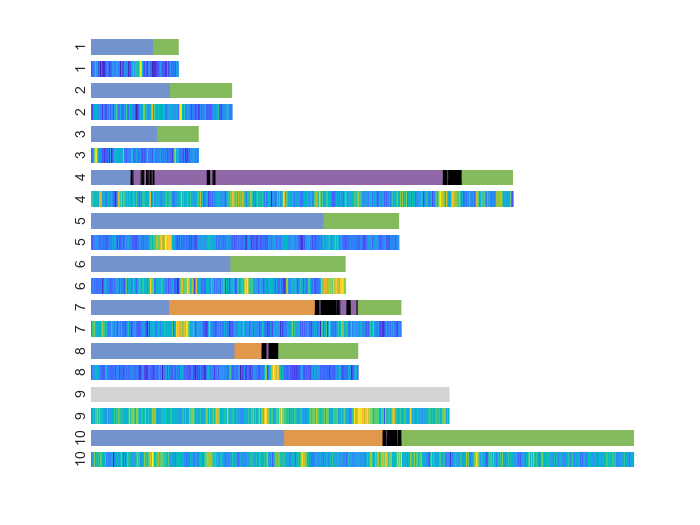

writetable(Data, animal_code + ".xlsx")
saveas(Visual, animal_code + "_visual_data.jpeg")

%cd(home);
clear
clc

function [spectTimes, filtSig, sig, spectFreqs, spectAmpVals] = ...
    sfoReadFibPhot(rawData, fs, freqRange, params)
    
    % Convert spectrogram window size and overlap from time to samples
    spectWindow = 2.^nextpow2(fs .* params.winSize);
    spectOverlap = ceil(spectWindow - (spectWindow .* (params.spectSample ./ params.winSize)));
    disp(['Spectrum window ', num2str(spectWindow ./ fs), ' sec; ',...
        num2str(spectWindow), ' samples at ', num2str(fs), ' Hz'])
    
    % Create low pass filter for final data
    lpFilt = designfilt('lowpassiir','FilterOrder',8, 'PassbandFrequency',params.filtCut,...
        'PassbandRipple',0.01, 'SampleRate',fs);
    
    % Calculate spectrogram
    [spectVals,spectFreqs,spectTimes]=spectrogram(rawData,spectWindow,spectOverlap,freqRange,fs);
    % Convert spectrogram to real units
    spectAmpVals = double(abs(spectVals));
    figure;
    imagesc(spectAmpVals);
    title('spectrogram');
    ylabel("Max Freq Bin");
    % Find the two carrier frequencies
    avgFreqAmps = mean(spectAmpVals,2);
    % [pks,locs]=findpeaks(double(avgFreqAmps),'minpeakheight',max(avgFreqAmps./10));
    [pks,locs]=findpeaks(double(avgFreqAmps));
    if max(pks) == 1 && length(pks) > 1
        pks(1) = []; locs(1) = [];
    end
    [maxVal,maxFreqBin] = max(pks);
    maxFreqBin = locs(maxFreqBin);
    yticks(maxFreqBin)
    % Calculate signal at each frequency band
    sig = mean(abs(spectVals((maxFreqBin-params.inclFreqWin):(maxFreqBin+params.inclFreqWin),:)),1);
    % Low pass filter the signals
    filtSig = filtfilt(lpFilt,double(sig));
end

function [ y ] = running_percentile(x, win, p, varargin)
    %RUNNING_PERCENTILE Median or percentile over a moving window.
    %   Y = RUNNING_PERCENTILE(X,WIN,P) returns percentiles of the values in 
    %   the vector Y over a moving window of size win, where p and win are
    %   scalars. p = 0 gives the rolling minimum, and p = 100 the maximum.
    %
    %   running_percentile(X,WIN,P,THRESH) includes a threshold where NaN will be
    %   returned in areas where the number of NaN values exceeds THRESH. If no
    %   value is specified the default is the window size / 2.
    %
    %   The definition used is the same as for MATLAB's prctile: if the
    %   window is too small for a given percentile, the max or min will be
    %   returned. Otherwise linear interpolation is used on the sorted data.
    %   Sorting is retained while updating the window, making this faster than
    %   repeatedly calling prctile. The edges are handled by duplicating nearby
    %   data.
    %
    %   Examples:
    %      y = running_percentile(x,500,10); % 10th percentile of x with
    %      a 500 point moving window
    
    %   Author: Levi Golston, 2014
    
    
    % Check inputs
    N = length(x);
    if win > N || win < 1
        error('window size must be <= size of X and >= 1')
    end
    if length(win) > 1
        error('win must be a scalar')
    end
    if p < 0 || p > 100
        error('percentile must be between 0 and 100')
    end
    if ceil(win) ~= floor(win)
        error('window size must be a whole number')
    end
    if ~isvector(x)
        error('x must be a vector')
    end
    
    if nargin == 4
        NaN_threshold = varargin{1};
    else
        NaN_threshold = floor(win/2);
    end
    
    % pad edges with data and sort first window
    if iscolumn(x)
        x = [x(ceil(win/2)-1 : -1 : 1); x; x(N : -1 : N-floor(win/2)+1); NaN];
    else
        x = [x(ceil(win/2)-1 : -1 : 1), x, x(N : -1 : N-floor(win/2)+1), NaN];
    end
    tmp = sort(x(1:win));
    y = NaN(N,1);
    
    offset = length(ceil(win/2)-1 : -1 : 1) + floor(win/2);
    numnans = sum(isnan(tmp));
    
    % loop
    for i = 1:N
	    % Percentile levels given by equation: 100/win*((1:win) - 0.5);
	    % solve for desired index
	    pt = p*(win-numnans)/100 + 0.5;
        if numnans > NaN_threshold   % do nothing
        elseif pt < 1        % not enough points: return min
		    y(i) = tmp(1);
	    elseif pt > win-numnans     % not enough points: return max
		    y(i) = tmp(win - numnans);
	    elseif floor(pt) == ceil(pt)  % exact match found
		    y(i) = tmp(pt);
	    else             % linear interpolation
		    pt = floor(pt);
		    x0 = 100*(pt-0.5)/(win - numnans);
		    x1 = 100*(pt+0.5)/(win - numnans);
		    xfactor = (p - x0)/(x1 - x0);
		    y(i) = tmp(pt) + (tmp(pt+1) - tmp(pt))*xfactor;
        end
        
	    % find index of oldest value in window
	    if isnan(x(i))
		    ix = win;  						  % NaN are stored at end of list
		    numnans = numnans - 1;
	    else
		    ix = find(tmp == x(i),1,'first');
	    end
	    
	    % replace with next item in data
	    newnum = x(offset + i + 1);
	    tmp(ix) = newnum;
	    if isnan(newnum)
		    numnans = numnans + 1;
	    end
	    tmp = sort(tmp);
    
    end
end

function shade_plot(start, stop, color)
    fill([start stop stop start], [0.1 0.1 0.9 0.9], color, 'EdgeColor', 'none');
end